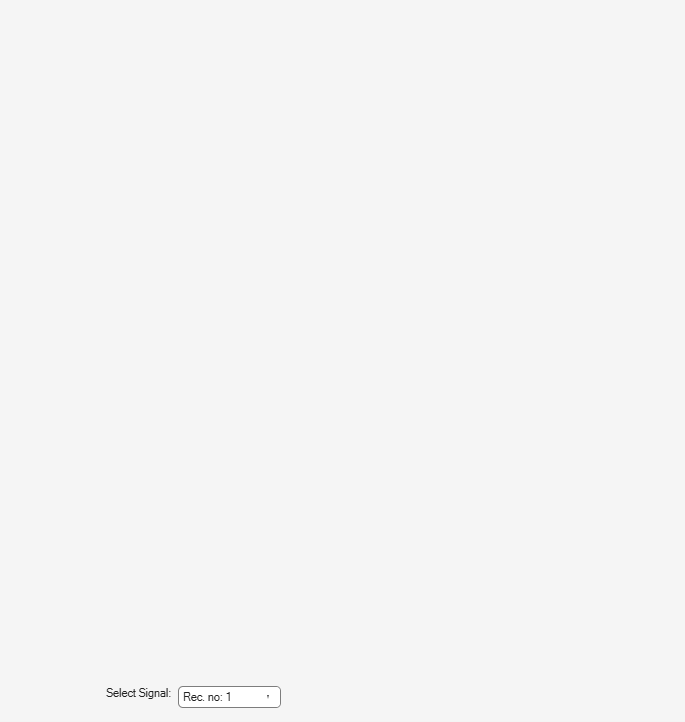

% Load result to be processed first

dpRespData = dbspl(dpResponse);
dbFFTResponse = dbspl(fftResponse);

freqDataVec = reshape(freqData, [], 1);
freqDataVec = freqDataVec(freqDataVec~=0);
dpRespDataVec = reshape(dpRespData, [], 1);
dpRespDataVec = dpRespDataVec(dpRespDataVec~=0);
nfVec = reshape(noiseFloor, [], 1);
nfVec = nfVec(nfVec~=0);
nfDataVec = dbspl(nfVec);

idxFreqDPVec = reshape(idxFreqDP, [], 1);

[~, DPOrderIndex] = sort(idxFreqDPVec);
[~, orderIndex] = sort(freqDataVec);

numSignals = size(fftResponse, 2);


fig=figure('units','normalized','outerposition',[0.3 0.1 0.4 0.8]);
tiledlayout(2,1,'padding','compact','tilespacing','compact')

nexttile
lnSpectrum=semilogx(freqFFT, dbFFTResponse,'linewidth',2);hold on
lnDPmarker=semilogx(freqFFT(idxFreqDPVec(DPOrderIndex)), dpRespDataVec(DPOrderIndex),'.','markersize',20);
xlim([100 20000]);ylim([-40 80])
xlabel('Frequency [Hz]');ylabel('dB SPL')
legendString = "Rec. no: ";
for i = 1:numSignals; labels(i) = legendString + num2str(i); end
labels(i+1) = "DPOAE";
legend(labels)

grid

nexttile
lnDPgram=semilogx(freqDataVec(orderIndex), nfDataVec(orderIndex),'.-','markersize',20,'linewidth',2);hold on
lnDPgramNoise=semilogx(freqDataVec(orderIndex), dpRespDataVec(orderIndex),'.-','markersize',20,'linewidth',2);
xlim([100 20000]);ylim([-40 40])
xlabel('Frequency [Hz]');ylabel('dB SPL')
legend('Noise','DPOAE')
grid
drawnow


% Current column tracker
currentCol = 1;

% Dropdown menu to select columns directly
uicontrol(fig, 'Style', 'text', 'String', 'Select Signal:', ...
    'Units', 'normalized', 'Position', [0.1, 0.02, 0.15, 0.03], 'HorizontalAlignment', 'right');

uiselect = uicontrol(fig, 'Style', 'popupmenu', ...
    'String', labels(1:numSignals), ...
    'Units', 'normalized', 'Position', [0.26, 0.02, 0.15, 0.03], ...
    'Callback', @(src, event) updatePlot(src.Value, lnSpectrum, dbFFTResponse, lnDPmarker, freqData, dpRespData));


function updatePlot(colIdx, fftFig, spectrum, pointFig, pointsX, pointsY)
    matlabColors = get(gca, 'ColorOrder');
    numColors = size(matlabColors, 1);

    uiselect.Value = colIdx; % Keep dropdown synced if button was pressed

    colorIdx = mod(colIdx, numColors+1);

    % Update the plot data dynamically
    set(fftFig, 'ydata', spectrum(:, colIdx), 'Color', matlabColors(colorIdx, :));
    set(pointFig, 'xdata', pointsX(:,colIdx), 'ydata', pointsY(:,colIdx), 'Color', matlabColors(abs(colorIdx-numColors-1), :))
    drawnow;
end